syms t s R L T
HS = R/(R+L*s)

$$HS = \frac{R}{R+L\,s}$$

ht=ilaplace(HS)

$$ht = \frac{R\,{\mathrm{e}}^{-\frac{R\,t}{L}}}{L}$$

ht=ht*heaviside(t)

$$ht = \frac{R\,{\mathrm{e}}^{-\frac{R\,t}{L}}\,\mathrm{heaviside}\left(t\right)}{L}$$

ht=subs(ht,R,1)

$$ht = \frac{{\mathrm{e}}^{-\frac{t}{L}}\,\mathrm{heaviside}\left(t\right)}{L}$$

ht=subs(ht,L,1)

$$ht = {\mathrm{e}}^{-t}\,\mathrm{heaviside}\left(t\right)$$

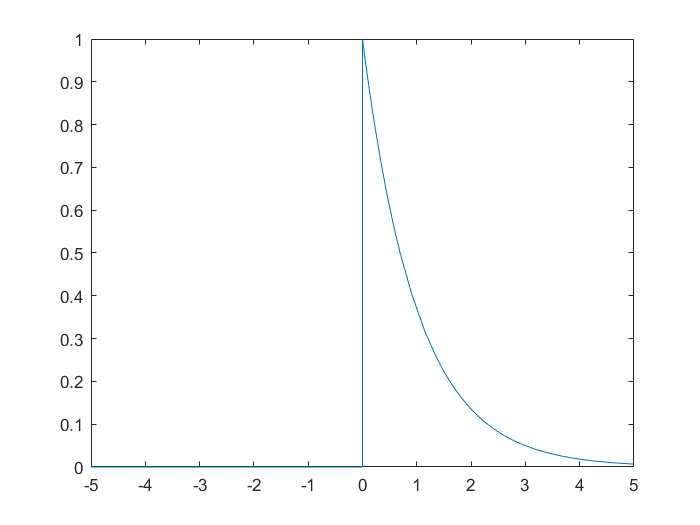

fplot(ht)

HS=laplace(ht)

$$HS = \frac{1}{s+1}$$

xt=heaviside(t)

$$xt = \mathrm{heaviside}\left(t\right)$$

XS=laplace(xt)

$$XS = \frac{1}{s}$$

YS=XS*HS

$$YS = \frac{1}{s\,\left(s+1\right)}$$

zt=ilaplace(YS)*heaviside(t)

$$zt = -\mathrm{heaviside}\left(t\right)\,\left({\mathrm{e}}^{-t}-1\right)$$

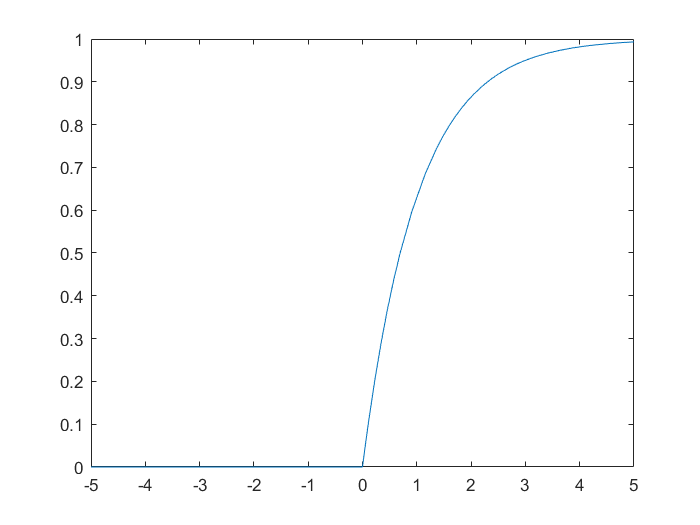

fplot(zt)

yt = exp(-2000*t)*heaviside(t) + exp(-1000*(t + 1))*heaviside(t - 1) + 2*exp(-1000)*heaviside(t - 1)

$$yt = \mathrm{heaviside}\left(t-1\right)\,{\mathrm{e}}^{-1000\,t-1000}+{\mathrm{e}}^{-2000\,t}\,\mathrm{heaviside}\left(t\right)$$

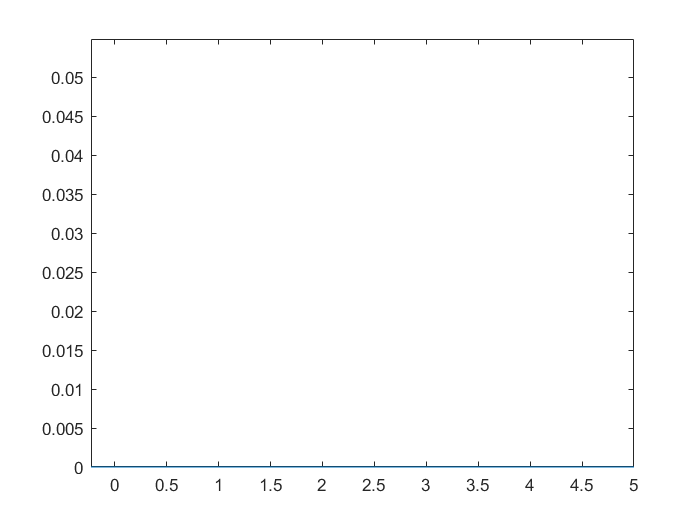

fplot(yt)

yt=heaviside(t)-heaviside(t-1)+exp(-(t-1))*heaviside(t-1)

$$yt = \mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-1\right)+\mathrm{heaviside}\left(t-1\right)\,{\mathrm{e}}^{1-t}$$

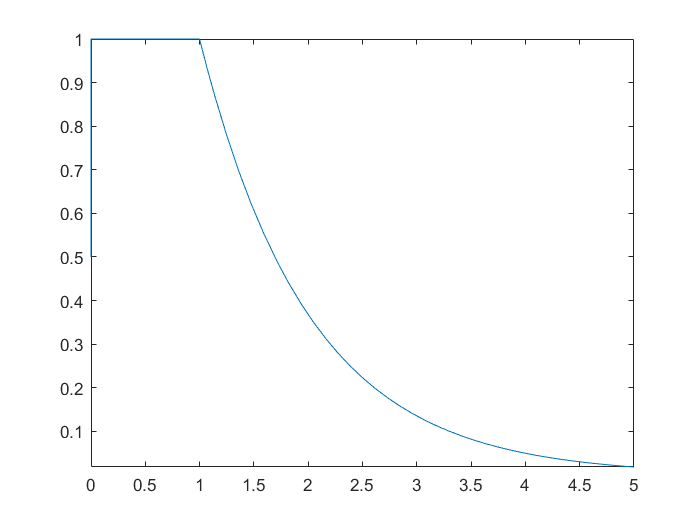

fplot(yt,[0 5])

yt = heaviside(t) - exp(-t)*heaviside(t)

$$yt = \mathrm{heaviside}\left(t\right)-{\mathrm{e}}^{-t}\,\mathrm{heaviside}\left(t\right)$$

fplot(yt)

yt=2*(-heaviside(t-1)+exp(-t+1)*heaviside(t-1))

$$yt = 2\,\mathrm{heaviside}\left(t-1\right)\,{\mathrm{e}}^{1-t}-2\,\mathrm{heaviside}\left(t-1\right)$$

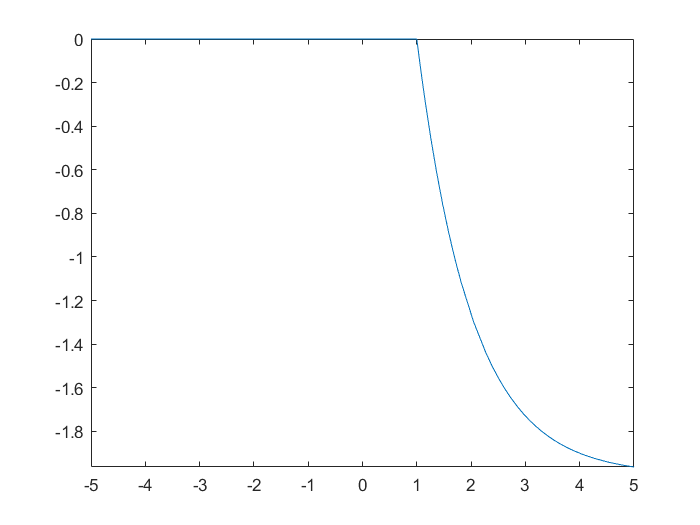

fplot(yt)

yt=zt-2*(heaviside(t-1)+exp(-t+1)*heaviside(t-1))+1

$$yt = -2\,\mathrm{heaviside}\left(t-1\right)-2\,\mathrm{heaviside}\left(t-1\right)\,{\mathrm{e}}^{1-t}-\mathrm{heaviside}\left(t\right)\,\left({\mathrm{e}}^{-t}-1\right)$$

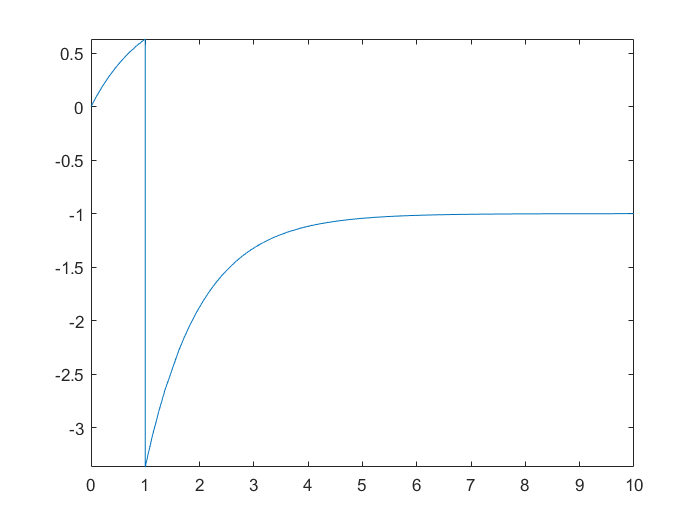

fplot(yt,[0 10])

xt=heaviside(t)-2*heaviside(t-1)+heaviside(t-2)

$$xt = \mathrm{heaviside}\left(t-2\right)-2\,\mathrm{heaviside}\left(t-1\right)+\mathrm{heaviside}\left(t\right)$$

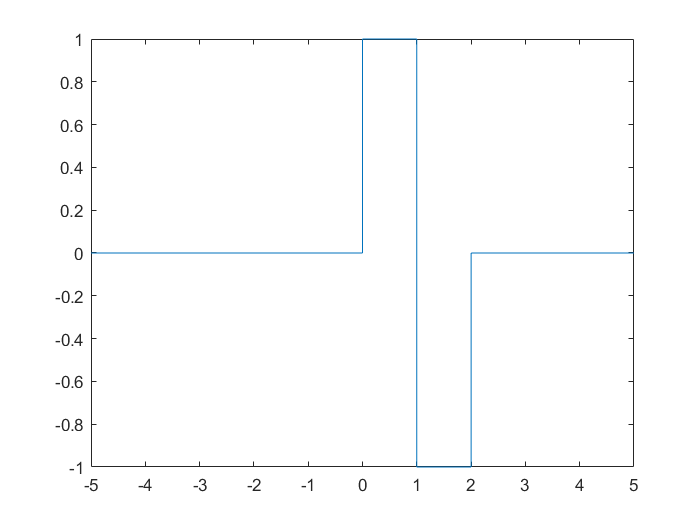

fplot(xt)

XS=laplace(xt)

$$XS = \frac{{\mathrm{e}}^{-2\,s}}{s}-\frac{2\,{\mathrm{e}}^{-s}}{s}+\frac{1}{s}$$

ZS=laplace(zt)

$$ZS = \frac{1}{s}-\frac{1}{s+1}$$

YS=XS*ZS

$$YS = -\left(\frac{1}{s+1}-\frac{1}{s}\right)\,\left(\frac{{\mathrm{e}}^{-2\,s}}{s}-\frac{2\,{\mathrm{e}}^{-s}}{s}+\frac{1}{s}\right)$$

yt=ilaplace(YS)*heaviside(t)

$$yt = \mathrm{heaviside}\left(t\right)\,\left(t+{\mathrm{e}}^{-t}-2\,\mathrm{heaviside}\left(t-1\right)\,\left(t-1\right)+\mathrm{heaviside}\left(t-2\right)\,\left(t-2\right)-2\,\mathrm{heaviside}\left(t-1\right)\,\left({\mathrm{e}}^{1-t}-1\right)+\mathrm{heaviside}\left(t-2\right)\,\left({\mathrm{e}}^{2-t}-1\right)-1\right)$$

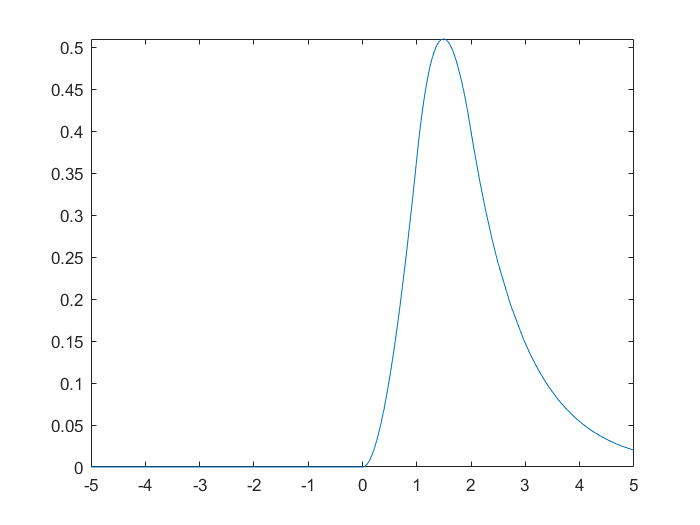



fplot(yt)